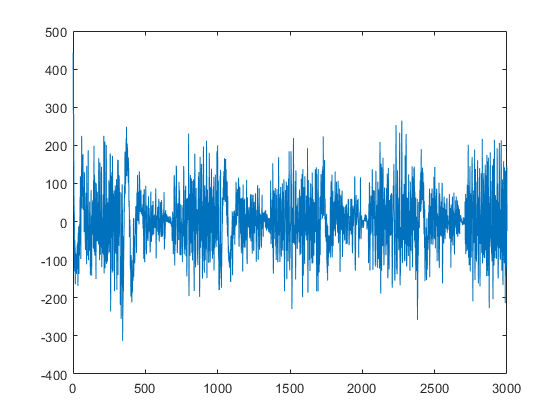

%%data
addpath('Z:\UNAIR\STUDY\SKRIPSI\DATA\DATA_odi2kg_(6.2)2019_10_1_2999');
data=csvread('DATA_odi2kg_(6.2)2019_10_1_2999.csv',1,1);
ti=data(:,4);
sudut=data(:,6);
emg=data(:,7);


%time sampling
tmax=max(ti);
tmin=min(ti);
[n nn]=size(ti);
ts=n/(tmax-tmin);
for i=1:n
    t(i)=(i-1)*ts;
end
%t=t';
%%filter emg dengan 10-500Hz, dengan notch filter 50Hz, dengan fs=1kHz
u=bpf_emg(emg,10,500,1000);
plot(u)

%%creat iddata with output input
z=iddata(sudut,u,ts)


z =

Time domain data set with 3000 samples.
Sample time: 0.130333 seconds           
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        


ze = z(1:2000); 
zv = z(2001:3000); 
m0 = nlarx(ze, [4 2 10], linear);
m0.InputName

ans = 1×1 cell array
    {'u1'}


m0.OutputName

ans = 1×1 cell array
    {'y1'}


getreg(m0)

Regressors:
    y1(t-1)
    y1(t-2)
    y1(t-3)
    y1(t-4)
    u1(t-10)
    u1(t-11)



m1 = nlarx(ze, [4 2 10], linear, 'customreg', {'u1(t-10)^2', 'y1(t-1)^2'});
getreg(m1)

Regressors:
    y1(t-1)
    y1(t-2)
    y1(t-3)
    y1(t-4)
    u1(t-10)
    u1(t-11)
    u1(t-10)^2
    y1(t-1)^2



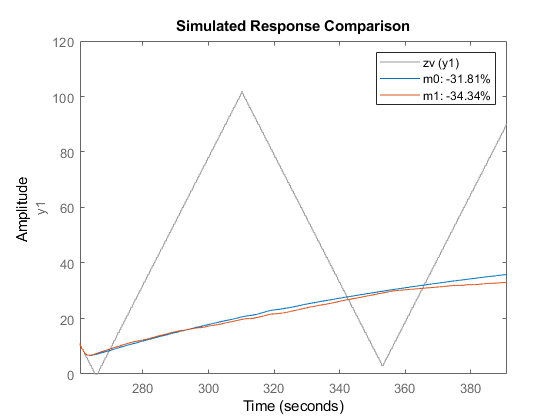

compare(zv,m0,m1)

m2 = nlarx(ze, [0 0 0], 'linear', 'customreg', ...
           {'u1(t-10)^3', 'u1(t-11)^3', 'y1(t-1)', 'sin(y1(t-4))'});
getreg(m2)

Regressors:
    u1(t-10)^3
    u1(t-11)^3
    y1(t-1)
    sin(y1(t-4))



m3 = nlarx(ze, [4 2 10], 'lin');
pr = polyreg(m3, 'maxpower', 2, 'crossterm', 'off');
m3 = addreg(m3, pr);
m3 = nlarx(ze, m3);

getreg(m3)

Regressors:
    y1(t-1)
    y1(t-2)
    y1(t-3)
    y1(t-4)
    u1(t-10)
    u1(t-11)
    y1(t-1).^2
    y1(t-2).^2
    y1(t-3).^2
    y1(t-4).^2
    u1(t-10).^2
    u1(t-11).^2



r1 = customreg(@cos, 'u1', 10, true) 

Custom Regressor: 
Expression: cos(u1(t-10))
        Function: @cos
       Arguments: {'u1'}
          Delays: 10
      Vectorized: 1
    TimeVariable: 't'



F = @(x1,x2,x3)sin(x1.*x2+x3); % Anonymous function
r2 = customreg(F, {'y1', 'u1', 'u1'}, [1 10 11], true)

Custom Regressor: 
Expression: sin(y1(t-1).*u1(t-10)+u1(t-11))
        Function: @(x1,x2,x3)sin(x1.*x2+x3)
       Arguments: {'y1'  'u1'  'u1'}
          Delays: [1 10 11]
      Vectorized: 1
    TimeVariable: 't'



m4 = nlarx(ze, [4 2 10], 'lin', 'customreg',  [r1;r2]);
getreg(m4)

Regressors:
    y1(t-1)
    y1(t-2)
    y1(t-3)
    y1(t-4)
    u1(t-10)
    u1(t-11)
    cos(u1(t-10))
    sin(y1(t-1).*u1(t-10)+u1(t-11))



m5 = nlarx(ze, [4 2 10], 'wavenet', 'customreg',  [r1;r2]);
getreg(m5)

Regressors:
    y1(t-1)
    y1(t-2)
    y1(t-3)
    y1(t-4)
    u1(t-10)
    u1(t-11)
    cos(u1(t-10))
    sin(y1(t-1).*u1(t-10)+u1(t-11))



m6 = nlarx(ze, [4 2 10], 'wavenet', 'customreg',  [r1;r2], 'nlreg', 'standard');
m6.nlreg % Indices of nonlinear regressors in the following list.

ans =      1     2     3     4     5     6


getreg(m6)

Regressors:
    y1(t-1)
    y1(t-2)
    y1(t-3)
    y1(t-4)
    u1(t-10)
    u1(t-11)
    cos(u1(t-10))
    sin(y1(t-1).*u1(t-10)+u1(t-11))



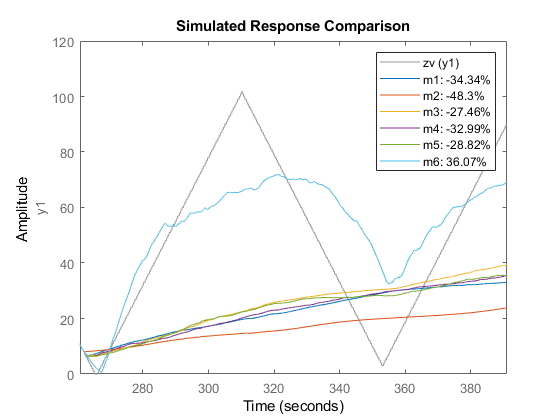

%%
% The various models can be compared together (may take a long time).

compare(zv, m1,m2,m3,m4,m5,m6)



% sys = addreg(sys, pr);
% sys = nlarx(z, sys);
% 
% getreg(sys)
% compare(z, sys)
% 
% 

